# Homework Guzzo Simone 0124001903

In conformità della traccia si è definita la seguente funzione "funrif" avente p che indica il numero di lettere presente nel nome e q che indica il numero di lettere presente nel cognome, come parametri di ingresso. Successivamente si è proceduto a definire un intervalllo, in cui poter visualizzare il grafico della nostra funzione di riferimento.

## Punto 1: Definizione Funzione di Riferimento

E' stato definito l'handle della funzione di riferimento, successivamente si è provveduto a plottare la funzione in un intervallo [a,b] ed in fine è stato sovrapposto al grafico una griglia attraverso il comando grid on.


$$F(x)=e^{-x} \cdot\left(\sin \left(\frac{p \cdot x}{2}-\pi / 2\right)\right)^{2}+\frac{q}{1+3 x^{2}} \sin (2 x)-5$$


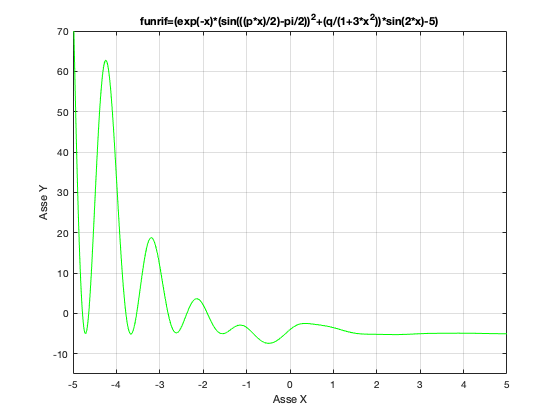

funrif= @(x) exp(-x).*(sin(((6.*x)./2)-pi./2)).^2+(5./(1+3.*x.^2)).*sin(2.*x)-5;
fplot(funrif,[-5,5],'g');
ylim([-15 70]);
title('funrif=(exp(-x)*(sin(((p*x)/2)-pi/2))^2+(q/(1+3*x^2))*sin(2*x)-5)')
xlabel('Asse X');
ylabel('Asse Y');
grid on;

## Punto 2: Visualizzazione grafico funzione di riferimento,i minimi,il massimo e gli zeri

Qui visualizzeremo il grafico della nostra funzione di riferimento nel intervallo presa in esame [-3, -1.3]


intervallo=[-3, -1.3];
fplot(funrif,intervallo,'-g',5);
ylim([-15 15]);
hold on;
plot(intervallo,[0 0],'k','LineWidth',1.3);
title('funrif nel intervallo [-3,-1.3]');
xlabel('Asse X');
ylabel('Asse Y');
grid on;


Si è utilizzata la function matlab fplot, andando a specificare la funzione e l'intervallo in cui visualizzarla 

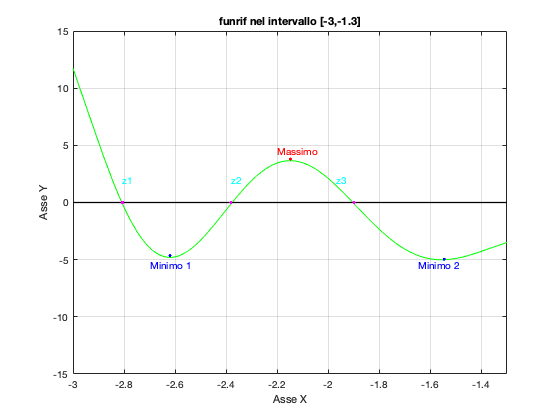

text(-2.807,2,'z1','Color','c','VerticalAlignment','middle');
text(-2.3827,2,'z2','Color','c','VerticalAlignment','middle');
text(-1.969,2,'z3','Color','c','VerticalAlignment','middle');
plot(-2.807,0,'.m','LineWidth',50);
plot(-2.382,0,'.m','LineWidth',50);
plot(-1.899,0,'.m','LineWidth',50);
text(-2.2,4.5,'Massimo','color','r','VerticalAlignment','middle');
text(-2.7,-5.5,'Minimo 1','color','b','VerticalAlignment','middle');
text(-1.65,-5.5,'Minimo 2','color','b','VerticalAlignment','middle');
plot(-2.149,3.8,'.r','LineWidth',50);
plot(-2.620,-4.65,'.b','LineWidth',50);
plot(-1.5466,-4.95,'.b','LineWidth',50);
hold off;

Di seguito, sono stati utilizzati i comandi text e plot per poter indetificare sul piano quali fossero i minimi, il massimo e i vari zeri.

## Punto 3: Determinazione degli Zeri

Per il calcolo degli zeri della funzione di riferimento andremo ad utilizzare la function fzero, basato sui metodi globali (che hanno convergenza assicurata) e locali (con velocità maggiore), ottenendo così ordini di grandezza superscalari o quadratici. Visto che matlab di default visualizza con una precisione decimale fino a 5 cifre, andremo ad utilizzare il comando format long in modo da visualizzare con una precisione maggiore le nostre variabili.

format long
z1=fzero(funrif,[-3 -2.8])

z1 =   -2.808946295201019


z2=fzero(funrif,[-2.4 -2.2])

z2 =   -2.376780122114007


z3=fzero(funrif,[-2 -1.8])

z3 =   -1.903532848725256


## Punto 4: Determinazione zeri della funzione bisezione, newton e secanti

In questo punto 4, per determinare le approssimazioni degli zeri della nostra funzione di riferimento, abbiamo utilizzato i metodi: Bisezion, Secanti e Newton. E' stato preso come accuratezza per le nostre approssimazioni un valore pari a 1e-07.

Il metodo di Bisezione, utilizza il principio del divide et impera. La funzione riceve in input la funzione di riferimento, 2 approssimazioni iniziali della soluzione e il delta assoluto.

Il metodo delle Secanti è un algoritmo iterativo locale a velocità di convergenza superlineare. La funzione Secanti riceve in input la funzione di riferimento, 2 approssimazioni iniziali della soluzione, l'accuratezza e il numero massimo di iterazioni che devono essere svolte dall'algoritmo, in modo da evitare che vada in loop.

Il metodo di Newton è un algoritmo iterativo locale e a velocità di convergenza quadratica. La funzione riceve in input la funzione di riferimento, la sua derivata, un'approssimazione della soluzione (determinata secondo certi criteri), l'accuratezza e il numero massimo di iterazioni che devono essere svolte dal algoritmo, in modo da evitare che vada in loop.

delta_ass = 1e-07;
fun_rif_dev=@(x)      (10.*cos(2.*x))./(3.*x.^2 + 1) - sin(3.*x - pi./2).^2.*exp(-x) - (30.*x.*sin(2.*x))./(3.*x.^2 + 1).^2 + 6.*cos(3.*x - pi./2).*sin(3.*x - pi./2).*exp(-x);

bisezione_z1 = bisezione(funrif,-3,-2.8,delta_ass)

bisezione_z1 =   -2.808946275711060


z1

z1 =   -2.808946295201019



secante_z2 = Secanti(funrif,-2.4,-2.3,delta_ass,10)

secante_z2 =   -2.376780150563084


z2

z2 =   -2.376780122114007



newton_z3 = Newton(funrif,fun_rif_dev,-1.895,delta_ass,10)

newton_z3 =   -1.903532848704913


z3

z3 =   -1.903532848725256


## Punto 5: Verifica delle accuratezze

Di seguito si confronta l'accuratezza richiesta (1e-07) sia con l'errore assoluto tra le soluzioni esatte e sia con le approssimazioni calcolate nel punto precedente.


abs(bisezione_z1-z1)<delta_ass

ans = logical
   1


abs(secante_z2-z2)<delta_ass

ans = logical
   1


abs(newton_z3-z3)<delta_ass

ans = logical
   1


L'espressione andrà a restituire 1 se il valore logico sarà True, mentre 0 se il valore logico sarà False.

Per trovare il residuo andiamo a calcolare la distanza tra il valore della funzione calcolata nel punto di approssimazione dallo zero meno il punto dove la funzione calcolata vale zero (ricavata da 'fzero'). 

Res_bisez = abs(bisezione_z1-z1)

Res_bisez =      1.948995898004569e-08


Res_secante = abs(secante_z2-z2)

Res_secante =      2.844907687205023e-08


Res_newton = abs(newton_z3-z3)

Res_newton =      2.034283852481167e-11


Andando ad osservare i residui ci rendiamo conto che il problema risulta essere ben condizionato, questo è dovuto dall'errore stesso che risulta essere più piccolo dell'accuratezza richiesta.

Continuiamo ora con il calcolo degli indici di condizionamento dando come x della nostra funzione derivata le approssimazioni degli zeri calcolati precedentemente con il metodo di bisezione, secanti e newton. Notiamo ora, che gli indici di condizionamento risultano essere molto piccoli, di conseguenza potremo dire che il problema risulta ben condizionato.

ind_condiz_z1=abs((fun_rif_dev(bisezione_z1))^-1)

ind_condiz_z1 =    0.020073117179498


ind_condiz_z2=abs((fun_rif_dev(secante_z2))^-1)

ind_condiz_z2 =    0.036249178326396


ind_condiz_z3=abs((fun_rif_dev(newton_z3))^-1)

ind_condiz_z3 =    0.042580008031314


## Punto 6: Calcolo minimi e massimi

Proseguiamo utilizzando la function fminbnd per poter calcolare i 2 punti di minimo e il punto di massimo, dando così in input la funzione (facendo attenzione per il massimo e fornendo in input l'inversa della funzione) e l'intervallo in cui si vuole determinare il minimo/massimo. Andremo a considerare i valori calcolati come esatti.

min1=fminbnd(funrif,-3,-2.5,optimset('TolX',1e-10))

min1 =   -2.619525004485351


min2=fminbnd(funrif,-2,-1.5,optimset('TolX',1e-10))

min2 =   -1.556269792919266


max=fminbnd(@(x)-funrif(x),-2.5,-2,optimset('TolX',1e-10))

max =   -2.149463930665388


## Punto 7: Verifica degli zeri dei Massimi e Minimi

Per poter dimostrare che i precedenti punti di Min e Max siano corretti dobbiamo calcolare gli zeri della nostra funzione di riferimento derivata e andarli a riportare graficamente in modo da esaminare se i punti di minimo e massimo corrispondono con gli zeri della derivata. Per fare ciò utilizzeremo la funzione fzero, dando in input la funzione di riferimento derivata e un intervallo in cui possiamo determinare gli zeri.

z1_dev = fzero(fun_rif_dev,[-2.8,-2.6])

z1_dev =   -2.619525009805264


min1

min1 =   -2.619525004485351


z2_dev = fzero(fun_rif_dev,[-2.2,-2])

z2_dev =   -2.149463919198321


max

max =   -2.149463930665388


z3_dev = fzero(fun_rif_dev,[-1.6,-1.4])

z3_dev =   -1.556269791887486


min2

min2 =   -1.556269792919266


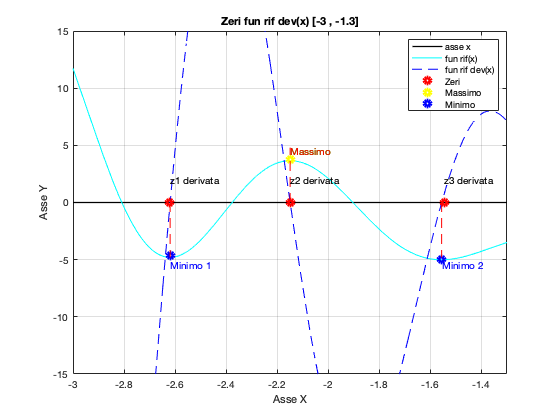


plot(intervallo,[0 0],'k','LineWidth',1.3);
hold on;
fplot(funrif,intervallo,'-c',5);
ylim([-15 15]);
xlim([-3 -1.3]);
hold on;

title('funrif=exp(-x)*(sin(((p*x)/2)-pi/2))^2+(q/(1+3*x^2))*sin(2*x)-5');
xlabel('Asse X');
ylabel('Asse Y');
grid on;

fplot(fun_rif_dev,intervallo,'--b');
title('Zeri fun rif dev(x) [-3 , -1.3]');
plot(-2.62044217,0,'or','LineWidth',3);
plot(max,3.8,'oy','LineWidth',3);
plot(min1,-4.65,'ob','LineWidth',3);
plot(-2.14947531,0,'or','LineWidth',3);
plot(-1.54666334,0,'or','LineWidth',3);
plot(min2,-4.95,'ob','LineWidth',3);
text(max,4.5,'Massimo','color','g','VerticalAlignment','middle');
text(min1,-5.5,'Minimo 1','color','b','VerticalAlignment','middle');
text(min2,-5.5,'Minimo 2','color','b','VerticalAlignment','middle');
plot([z1_dev min1],[0 -4.8],'--r');
plot([z2_dev max],[0 4.8],'--r');
plot([z3_dev min2],[0 -4.8],'--r');
legend('asse x','fun rif(x)','fun rif dev(x)','Zeri','Massimo','Minimo','location','NorthEast');
text(max,4.5,'Massimo','color','r','VerticalAlignment','middle');


text(-2.62044217,2,'z1 derivata','Color','k','VerticalAlignment','middle');
text(-2.14947531,2,'z2 derivata','Color','k','VerticalAlignment','middle');
text(-1.54666334,2,'z3 derivata','Color','k','VerticalAlignment','middle');

## Punto 8: Punti di Minimo tramite Golden Search e punto di Massimo tramite Fibonacci Search

Andiamo a determinare i punti di minimo della funzione di riferimento mediante la Golden Search (Ricerca Aurea) con un'accuratezza delta_ass = 1e-04.

%FunRif,l'intervallo al interno del quale è racchiuso il minimo come specificato
% nei precedenti punti un accuratezza delta_ass = 1e-04.
delta_ass=1e-04;

Il metodo della Golden Search presenta similitudini con il comportamento del metodo di Fibonacci, la differenza tra i due sta nella modalità di determinazione dei punti c e d, come verrà mostrato di seguito riprendono la definizione di sezione aurea $$\lim_{N \to + \infty} \frac{F_{N}} {F_{N-1}} = \varphi$: $d = a+ (\varphi-1)[b-a]$ $c = a+(2- \varphi)[b-a]$$ .

 Eseguiremo quindi il calcolo dei punti di massimo e il confronto con il  massimo esatto.

Golden_Max = fmingolden(@(x)- funrif(x),-2.2,-2,delta_ass), max

Golden_Max =   -2.149488846612351


max =   -2.149463930665388


Il metodo di ricerca di Fibonacci comincia andando a scegliere un intero N, che indica il numero di iterazioni, con un criterio basato sulla seguente equazione:


$$$$ N=\frac{[log(b-a)-log(\delta)]}{log(\varphi)} $$$$


($$[b-a]$$ ampiezza dell'intervalo iniziale, $$delta$$ massimo errore tollerato sull'approssimazone, $$varphi$$ sezione aurea)

Questo metodo è perfetto per quanto riguarda la velocità di convergenza, nonostante ciò non c'è la possibilità di trovare un metodo che, applicato a qualunque funzione unimodale, riduca l'incertezza iniziale più di quanto faccia il metodo di ricerca di Fibonacci.

La funzione fminfibo prende in input la FunRif,gli estremi[a,b] dell'intervallo che contiene la soluzione e delta_ass, l'accuratezza che desideriamo sulla soluzione.

Ora procederemo con il calcolo dei punti di minimo, andadoli poi a confrontare con le soluzioni esatte min1 e min2. Successivamente si è provveduto a effettuare vari test, riducendo man mano l'ampiezza dell'intervallo:

Min1_Fibo = fminfibo(funrif,-2.62,-2.6157,delta_ass), min1

Min1_Fibo =   -2.619503846153846


min1 =   -2.619525004485351


Min2_Fibo = fminfibo(funrif,-1.7,-1.5,delta_ass), min2

Min2_Fibo =   -1.556229508196721


min2 =   -1.556269792919266


## Punto 9: Verica dell'accuratezze Fibonacci Search e Golden Search

delta_ass=1e-04;
abs(Min1_Fibo-min1)<delta_ass

ans = logical
   1


abs(Min2_Fibo-min2)<delta_ass

ans = logical
   1


abs(Golden_Max-max)<delta_ass

ans = logical
   1


Come è possibile notare, si deduce che i risultati richiesti hanno un'accuratezza pari a 1e-04.